# MPC Assignment 2 - Alireza Amiri

## 2. Question 1

## 2. Question 2

%% create MPC controller object with sample time
mpc1 = mpc(plant_C_1, 0.3);
%% specify prediction horizon
mpc1.PredictionHorizon = 200;
%% specify control horizon
mpc1.ControlHorizon = 40;
%% specify nominal values for inputs and outputs
mpc1.Model.Nominal.U = [0;0];
mpc1.Model.Nominal.Y = [0;0];
%% specify constraints for MV and MV Rate
mpc1.MV(1).Min = -50;
mpc1.MV(1).Max = 50;
mpc1.MV(1).RateMin = -5;
mpc1.MV(1).RateMax = 5;
mpc1.MV(2).Min = -20;
mpc1.MV(2).Max = 20;
mpc1.MV(2).RateMin = -3;
mpc1.MV(2).RateMax = 3;
%% specify constraints for OV
mpc1.OV(1).Min = -15;
mpc1.OV(1).Max = 25;
mpc1.OV(2).Min = -30;
mpc1.OV(2).Max = 40;
%% specify overall adjustment factor applied to weights
beta = 4.7588;
%% specify weights
mpc1.Weights.MV = [0.1 0.1]*beta;
mpc1.Weights.MVRate = [0.1 0.1]/beta;
mpc1.Weights.OV = [20 20]*beta;
mpc1.Weights.ECR = 100000;
%% specify simulation options
options = mpcsimopt();
options.RefLookAhead = 'off';
options.MDLookAhead = 'off';
options.Constraints = 'on';
options.OpenLoop = 'off';
%% run simulation
sim(mpc1, 34, mpc1_RefSignal, mpc1_MDSignal, options);


## 2. Question 3

### part 1

% Define state-space matrices
A = [0    0    1     0;
     0    0    0     1;
     0 -698.30 -416.80 416.80;
     0  139.96   53.41  -53.41];

B = [0     0;
     0     0;
   405.11 405.11;
   -51.91 -51.91];

C = eye(4); % Identity matrix for full-state output
D = zeros(4, 2); % No direct feedthrough

% Create state-space system
sys = ss(A, B, C, D);

% Find poles, zeros, and gain
[z, p, k] = zpkdata(sys, 'v'); % Zeros, poles, gain

% Display results
fprintf('Zeros of the system:\n');

Zeros of the system:


z

z = 4×2 cell array
    {2×1 double}    {2×1 double}
    {[  0.0161]}    {[  0.0161]}
    {2×1 double}    {2×1 double}
    {2×1 double}    {2×1 double}


fprintf('Poles of the system:\n');

Poles of the system:


p

p = 4×2 cell array
    {4×1 double}    {4×1 double}
    {3×1 double}    {3×1 double}
    {3×1 double}    {3×1 double}
    {3×1 double}    {3×1 double}


fprintf('Gain of the system:\n');

Gain of the system:


k

k =   405.1100  405.1100
  -51.9100  -51.9100
  405.1100  405.1100
  -51.9100  -51.9100


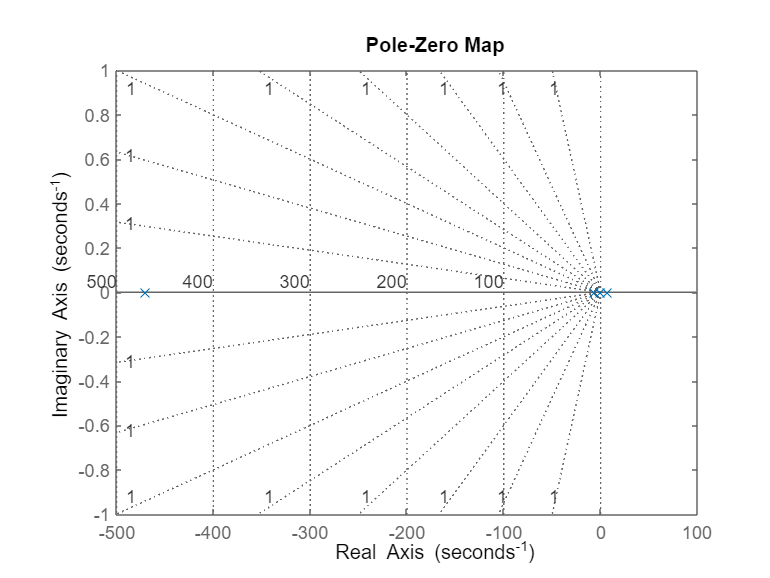


% Plot poles and zeros
figure;
pzmap(sys);
grid on;

title('Pole-Zero Map');

% Check Controllability
ControllabilityMatrix = ctrb(A, B); % Controllability matrix
if rank(ControllabilityMatrix) == size(A, 1)
    fprintf('The system is controllable.\n');
else
    fprintf('The system is NOT controllable.\n');
end

The system is controllable.



% Check Observability
ObservabilityMatrix = obsv(A, C); % Observability matrix
if rank(ObservabilityMatrix) == size(A, 1)
    fprintf('The system is observable.\n');
else
    fprintf('The system is NOT observable.\n');
end

The system is observable.



% Output matrices for verification
fprintf('\nControllability Matrix:\n');


Controllability Matrix:


disp(ControllabilityMatrix);

   1.0e+10 *

         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0090    0.0090
         0         0   -0.0000   -0.0000    0.0000    0.0000   -0.0011   -0.0011
    0.0000    0.0000   -0.0000   -0.0000    0.0090    0.0090   -4.2151   -4.2151
   -0.0000   -0.0000    0.0000    0.0000   -0.0011   -0.0011    0.5403    0.5403



fprintf('Observability Matrix:\n');

Observability Matrix:


disp(ObservabilityMatrix);

   1.0e+08 *

    0.0000         0         0         0
         0    0.0000         0         0
         0         0    0.0000         0
         0         0         0    0.0000
         0         0    0.0000         0
         0         0         0    0.0000
         0   -0.0000   -0.0000    0.0000
         0    0.0000    0.0000   -0.0000
         0   -0.0000   -0.0000    0.0000
         0    0.0000    0.0000   -0.0000
         0    0.0035    0.0020   -0.0020
         0   -0.0004   -0.0003    0.0003
         0    0.0035    0.0020   -0.0020
         0   -0.0004   -0.0003    0.0003
         0   -1.6438   -0.9219    0.9254
         0    0.2107    0.1182   -0.1186



### Part 2

% Define sampling time (e.g., 0.01 seconds)
Ts = 0.1;

% Initial condition
x0 = [0; 0.1; 0; 0];

% Discretize the system
sys_discrete = c2d(sys, Ts);

% Extract discretized state-space matrices
Ad = sys_discrete.A;
Bd = sys_discrete.B;
Cd = sys_discrete.C;
Dd = sys_discrete.D;

% Store the matrices for future use
save('discretized_matrices.mat', 'Ad', 'Bd', 'Cd', 'Dd');

% Find zeros, poles, and gain of the discretized system
[z_d, p_d, k_d] = zpkdata(sys_discrete, 'v'); % 'v' ensures numeric values

% Display results
fprintf('Zeros of the discretized system:\n');

Zeros of the discretized system:


z_d

z_d = 4×2 cell array
    {3×1 double}    {3×1 double}
    {2×1 double}    {2×1 double}
    {2×1 double}    {2×1 double}
    {2×1 double}    {2×1 double}


fprintf('Poles of the discretized system:\n');

Poles of the discretized system:


p_d

p_d = 4×2 cell array
    {4×1 double}    {4×1 double}
    {3×1 double}    {3×1 double}
    {3×1 double}    {3×1 double}
    {3×1 double}    {3×1 double}


fprintf('Gain of the discretized system:\n');

Gain of the discretized system:


k_d

k_d =     0.0844    0.0844
   -0.0117   -0.0117
    0.8551    0.8551
   -0.1372   -0.1372


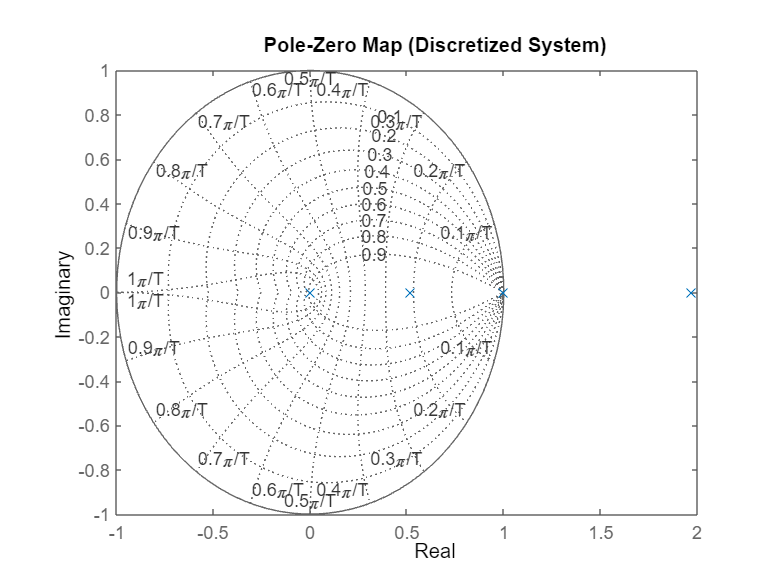


% Plot poles and zeros of the discretized system
figure;
pzmap(sys_discrete);
grid on;
title('Pole-Zero Map (Discretized System)');
xlabel('Real');
ylabel('Imaginary');

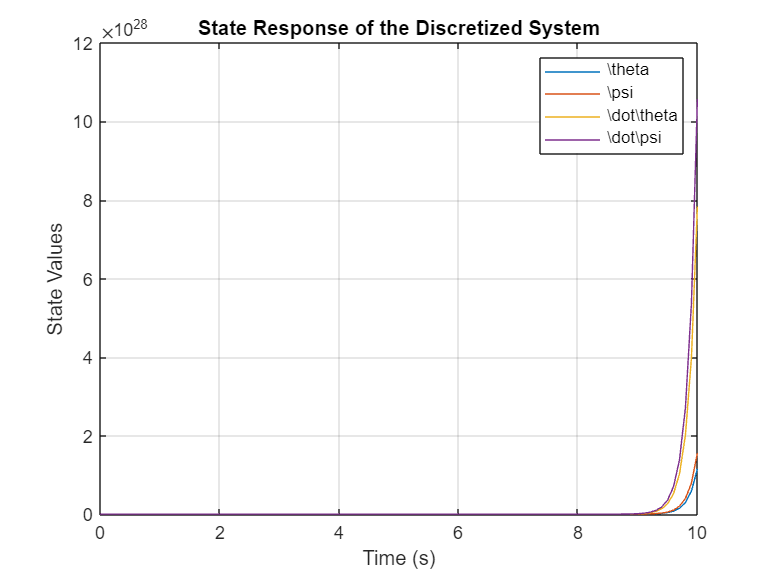


% Simulate the discretized system with the initial condition
time = 0:Ts:10; % Simulate for 1 second
u = zeros(length(time), 2); % Assuming zero input for simplicity
[y_discrete, t_discrete, x_discrete] = lsim(sys_discrete, u, time, x0);

% Plot the simulation results
figure;
plot(t_discrete, x_discrete);
grid on;
title('State Response of the Discretized System');
xlabel('Time (s)');
ylabel('State Values');
legend('\\theta', '\\psi', '\\dot{\\theta}', '\\dot{\\psi}');

### Part 3

#### Linear MPC

%% create MPC1 controller object with sample time
mpc1 = mpc(plant_C, 0.1);

-->The "PredictionHorizon" property is empty. Assuming default 10.
-->The "ControlHorizon" property is empty. Assuming default 2.
-->The "Weights.ManipulatedVariables" property is empty. Assuming default 0.00000.
-->The "Weights.ManipulatedVariablesRate" property is empty. Assuming default 0.10000.
-->The "Weights.OutputVariables" property is empty. Assuming default 1.00000.
   for output(s) y1 y2 and zero weight for output(s) y3 y4 


%% specify prediction horizon
mpc1.PredictionHorizon = 20;
%% specify control horizon
mpc1.ControlHorizon = 10;
%% specify nominal values for inputs and outputs
mpc1.Model.Nominal.U = [0;0];
mpc1.Model.Nominal.Y = [0;0.1;0;0];
%% specify overall adjustment factor applied to weights
beta = 2.7183;
%% specify weights
mpc1.Weights.MV = [0 0]*beta;
mpc1.Weights.MVRate = [0.1 0.1]/beta;
mpc1.Weights.OV = [1 1 0 0]*beta;
mpc1.Weights.ECR = 100000;
%% specify overall adjustment factor applied to estimation model gains
alpha = 10;
%% adjust default output disturbance model gains
setoutdist(mpc1, 'model', getoutdist(mpc1)*alpha);

-->Resampling the "Model.Plant" property to controller's sample time.
   Assuming no disturbance added to measured output channel #1.
-->Assuming output disturbance added to measured output channel #2 is integrated white noise.
-->Assuming output disturbance added to measured output channel #3 is integrated white noise.
-->Assuming output disturbance added to measured output channel #4 is integrated white noise.
-->The "Model.Noise" property is empty. Assuming white noise on each measured output.


%% adjust default measurement noise model gains
mpc1.Model.Noise = mpc1.Model.Noise/alpha;
%% specify simulation options
options = mpcsimopt();
options.RefLookAhead = 'off';
options.MDLookAhead = 'off';
options.Constraints = 'on';
options.OpenLoop = 'off';
%% run simulation
sim(mpc1, 1001, mpc1_RefSignal, mpc1_MDSignal, options);

Unrecognized function or variable 'mpc1_RefSignal'.

#### LQR

Ad

Ad =     1.0000    0.0661    0.0132    0.0866
         0    1.2551    0.0120    0.0966
         0    2.8959    0.1204    0.9457
         0    5.1145    0.1414    1.1138


Bd

Bd =     0.0844    0.0844
   -0.0117   -0.0117
    0.8551    0.8551
   -0.1372   -0.1372


Cd

Cd =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Dd

Dd =      0     0
     0     0
     0     0
     0     0


q = [100,0,0,0; 0,100,0,0; 0,0,10,0 ; 0,0,0,10]

q =    100     0     0     0
     0   100     0     0
     0     0    10     0
     0     0     0    10


r = eye(width(Bd))

r =      1     0
     0     1


[k_LQR,s_LQR,p_LQR] = dlqr(Ad,Bd,q,r)

k_LQR =    -0.7434  -60.6744   -1.0184   -8.0624
   -0.7434  -60.6744   -1.0184   -8.0624


s_LQR = 1.0e+05 *

    0.0067    0.0793    0.0014    0.0111
    0.0793    2.1697    0.0381    0.3005
    0.0014    0.0381    0.0008    0.0053
    0.0111    0.3005    0.0053    0.0418


p_LQR =    0.7348 + 0.0000i
   0.4950 + 0.0215i
   0.4950 - 0.0215i
  -0.0000 + 0.0000i


## 2. Question 4

MPC_Part4_Soft

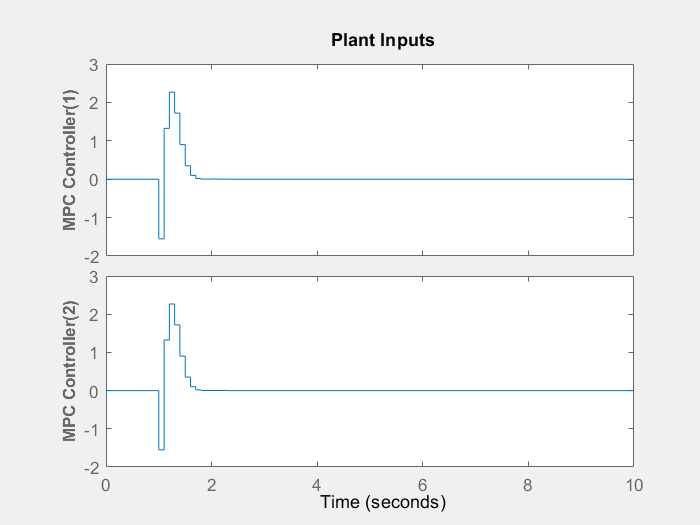

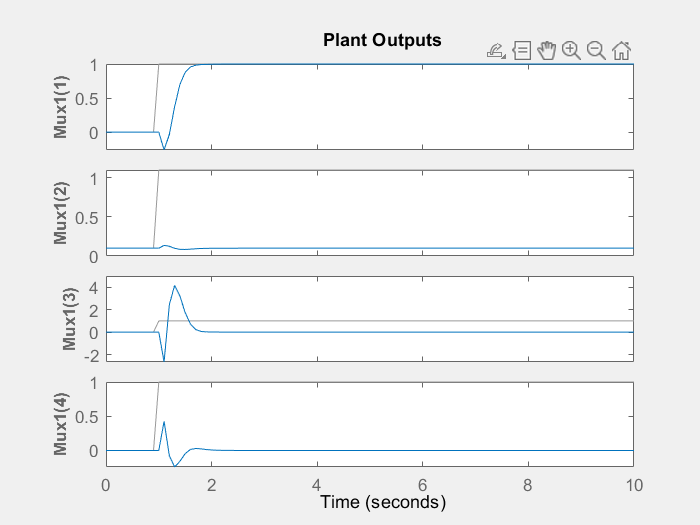

%% create MPC controller object with sample time
MPC_Part4_Soft = mpc(MPC_Part4_Soft_plant_C, 0.1);
%% specify prediction horizon
MPC_Part4_Soft.PredictionHorizon = 20;
%% specify control horizon
MPC_Part4_Soft.ControlHorizon = 10;
%% specify nominal values for inputs and outputs
MPC_Part4_Soft.Model.Nominal.U = [0;0];
MPC_Part4_Soft.Model.Nominal.Y = [0;0.1;0;0];
%% specify constraints for OV
MPC_Part4_Soft.OV(1).Min = -0.3;
MPC_Part4_Soft.OV(1).Max = 1.5;
%% specify weights
MPC_Part4_Soft.Weights.MV = [0 0];
MPC_Part4_Soft.Weights.MVRate = [0.1 0.1];
MPC_Part4_Soft.Weights.OV = [1 1 0 0];
MPC_Part4_Soft.Weights.ECR = 100000;
%% specify simulation options
options = mpcsimopt();
options.RefLookAhead = 'off';
options.MDLookAhead = 'off';
options.Constraints = 'on';
options.OpenLoop = 'off';
%% run simulation
sim(MPC_Part4_Soft, 101, MPC_Part4_Soft_RefSignal, MPC_Part4_Soft_MDSignal, options);

MPC_Part4_Hard

%% create MPC controller object with sample time
MPC_Part4_Hard = mpc(plant_C, 0.1);

-->The "PredictionHorizon" property is empty. Assuming default 10.
-->The "ControlHorizon" property is empty. Assuming default 2.
-->The "Weights.ManipulatedVariables" property is empty. Assuming default 0.00000.
-->The "Weights.ManipulatedVariablesRate" property is empty. Assuming default 0.10000.
-->The "Weights.OutputVariables" property is empty. Assuming default 1.00000.
   for output(s) y1 y2 and zero weight for output(s) y3 y4 


%% specify prediction horizon
MPC_Part4_Hard.PredictionHorizon = 20;
%% specify control horizon
MPC_Part4_Hard.ControlHorizon = 10;
%% specify nominal values for inputs and outputs
MPC_Part4_Hard.Model.Nominal.U = [0;0];
MPC_Part4_Hard.Model.Nominal.Y = [0;0.1;0;0];
%% specify constraints for OV
MPC_Part4_Hard.OV(1).Min = -0.3;
MPC_Part4_Hard.OV(1).Max = 1.5;
%% specify constraint softening for OV
MPC_Part4_Hard.OV(1).MinECR = 0;
MPC_Part4_Hard.OV(1).MaxECR = 0;
%% specify weights
MPC_Part4_Hard.Weights.MV = [0 0];
MPC_Part4_Hard.Weights.MVRate = [0.1 0.1];
MPC_Part4_Hard.Weights.OV = [1 1 0 0];
MPC_Part4_Hard.Weights.ECR = 100000;
%% specify simulation options
options = mpcsimopt();
options.RefLookAhead = 'off';
options.MDLookAhead = 'off';
options.Constraints = 'on';
options.OpenLoop = 'off';
%% run simulation

Unrecognized function or variable 'MPC_Part4_Hard_RefSignal'.

sim(MPC_Part4_Hard, 1001, MPC_Part4_Hard_RefSignal, MPC_Part4_Hard_MDSignal, options);

## 2. Question 5

MPC_Part5_Hard

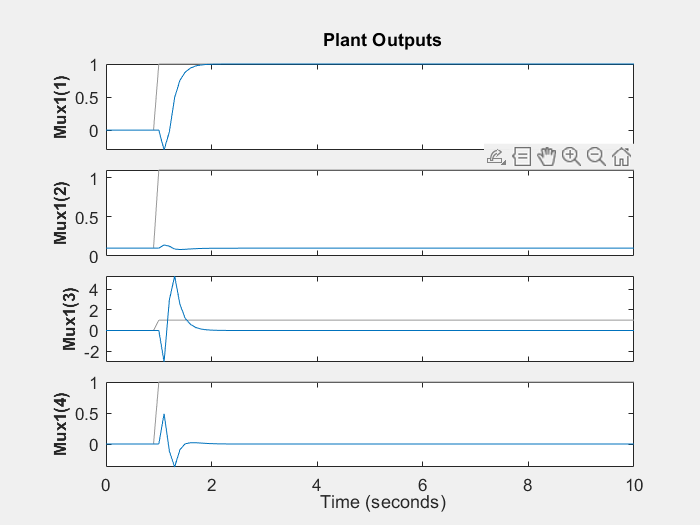

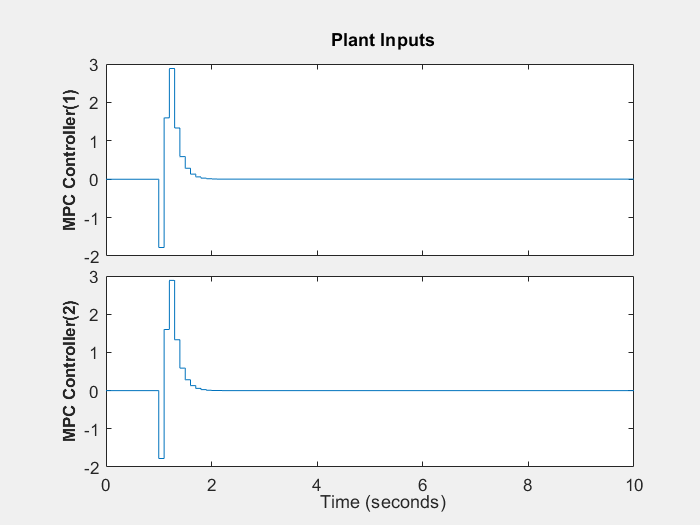

%% create MPC controller object with sample time
MPC_Part5_Hard = mpc(MPC_Part5_Hard_plant_C, 0.1);
%% specify prediction horizon
MPC_Part5_Hard.PredictionHorizon = 20;
%% specify control horizon
MPC_Part5_Hard.ControlHorizon = 10;
%% specify nominal values for inputs and outputs
MPC_Part5_Hard.Model.Nominal.U = [0;0];
MPC_Part5_Hard.Model.Nominal.Y = [0;0.1;0;0];
%% specify constraints for OV
MPC_Part5_Hard.OV(1).Min = -0.3;
MPC_Part5_Hard.OV(1).Max = 1.6;
%% specify constraint softening for OV
MPC_Part5_Hard.OV(1).MinECR = 0;
MPC_Part5_Hard.OV(1).MaxECR = 0;
%% specify overall adjustment factor applied to weights
beta = 3.3201;
%% specify weights
MPC_Part5_Hard.Weights.MV = [0 0]*beta;
MPC_Part5_Hard.Weights.MVRate = [0.1 0.1]/beta;
MPC_Part5_Hard.Weights.OV = [1 1 0 0]*beta;
MPC_Part5_Hard.Weights.ECR = 100000;
%% specify overall adjustment factor applied to estimation model gains
alpha = 0.36308;
%% adjust default output disturbance model gains
setoutdist(MPC_Part5_Hard, 'model', getoutdist(MPC_Part5_Hard)*alpha);
%% adjust default measurement noise model gains
MPC_Part5_Hard.Model.Noise = MPC_Part5_Hard.Model.Noise/alpha;
%% specify simulation options
options = mpcsimopt();
options.RefLookAhead = 'off';
options.MDLookAhead = 'off';
options.Constraints = 'on';
options.OpenLoop = 'off';
%% run simulation
sim(MPC_Part5_Hard, 101, MPC_Part5_Hard_RefSignal, MPC_Part5_Hard_MDSignal, options);

MPC_Part5_Soft

%% create MPC controller object with sample time
MPC_Part5_Soft = mpc(plant_C, 0.1);
%% specify prediction horizon
MPC_Part5_Soft.PredictionHorizon = 20;
%% specify control horizon
MPC_Part5_Soft.ControlHorizon = 10;
%% specify nominal values for inputs and outputs
MPC_Part5_Soft.Model.Nominal.U = [0;0];
MPC_Part5_Soft.Model.Nominal.Y = [0;0.1;0;0];
%% specify constraints for OV
MPC_Part5_Soft.OV(1).Min = -0.3;
MPC_Part5_Soft.OV(1).Max = 1.6;
%% specify weights
MPC_Part5_Soft.Weights.MV = [0 0];
MPC_Part5_Soft.Weights.MVRate = [0.1 0.1];
MPC_Part5_Soft.Weights.OV = [1 1 0 0];
MPC_Part5_Soft.Weights.ECR = 100000;
%% specify simulation options
options = mpcsimopt();
options.RefLookAhead = 'off';
options.MDLookAhead = 'off';
options.Constraints = 'on';
options.OpenLoop = 'off';
%% run simulation
sim(MPC_Part5_Soft, 1001, MPC_Part4_Soft_RefSignal, MPC_Part4_Soft_MDSignal, options);

Unrecognized function or variable 'MPC_Part5_Soft_RefSignal'.